Muesta unitario

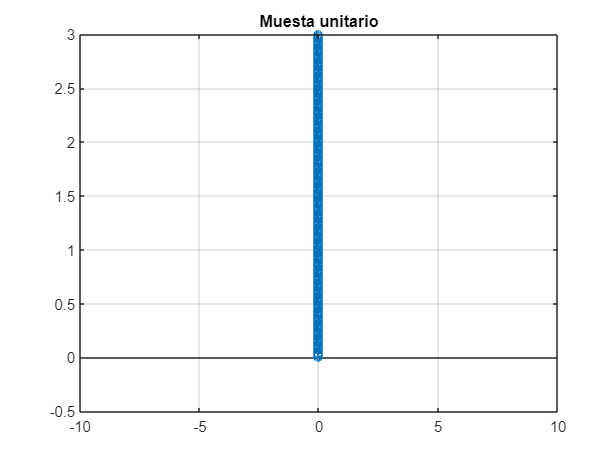

t = 0:0.01:10;
delta = zeros(size(t));
delta(t == 0) = Inf;
figure;
stem(delta,t );
title("Muesta unitario")
hold on;
grid on;
axis([-10 10 -0.5 3]);

Escalon Unidad

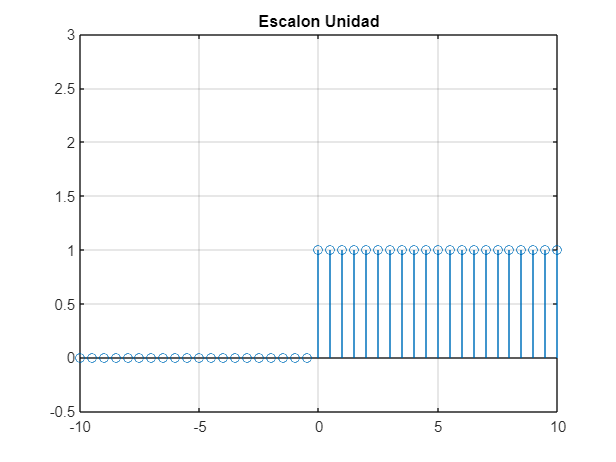

t = -10:0.5:10;
escalonUnidad = zeros(size(t));
for i = 1:length(t)
    if t(i) >= 0
        escalonUnidad(i) = 1;
    end
end

figure;

stem(t, escalonUnidad);
title("Escalon Unidad")
hold on;
grid on;
axis([-10 10 -0.5 3]);

Rampa Unidad

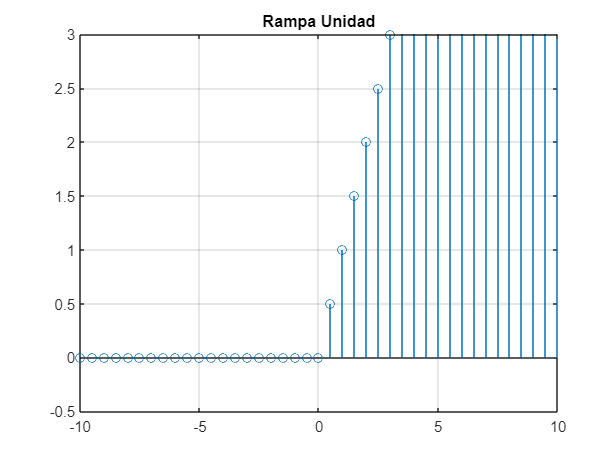

t = -10:0.5:10;
RamUnidad = zeros(size(t));

for i = 1:length(t)
    if t(i) >= 0
       RamUnidad(i) = 1; % u(t) es igual a 1 cuando t es mayor o igual a 0
    else
        RamUnidad(i) = 0; % u(t) es igual a 0 cuando t es menor que 0
    end
end

y = t .* RamUnidad;
figure;
stem(t, y);
title("Rampa Unidad")
hold on;
grid on;
axis([-10 10 -0.5 3]);

Señal Exponencia

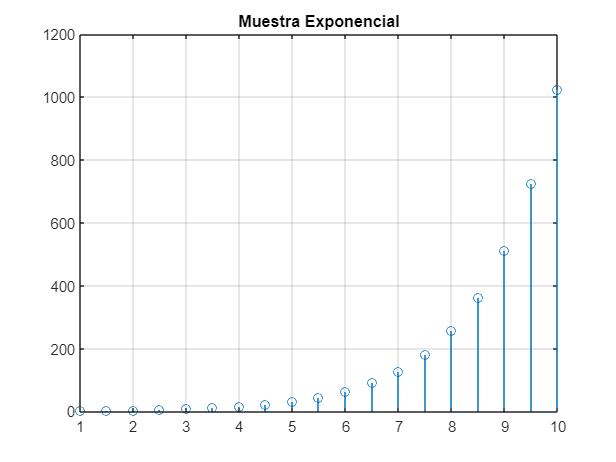

a = 2;
n = 1:0.5:10;
exponencial = zeros(size(n));
for i = 1:length(n)
    exponencial(i) = a^n(i);
end
figure;
stem(n, exponencial);
hold on;
grid on;
title('Muestra Exponencial');